clear all;
close all;
clc;


## Projeto do Conversor Buck


%Tensão de entrada CC (V)
Vin =24; 

%Tensão de saída (V)
Vout = 12;

%Potência de saída (W)
Pout = 100;

%Resistência de carga (ohms)
RL = Vout^2/Pout         % 100% de carga

RL = 1.4400

RL50 = Vout^2/(0.5*Pout) % 50% de carga

RL50 = 2.8800

RL10 = Vout^2/(0.1*Pout) % 10% de carga

RL10 = 14.4000

RL1 = Vout^2/(0.001*Pout) % 1% de carga

RL1 = 1440


%Frequência de comutação (Hz)
fs = 50000;

%Riple de corrente no indutor (%)
Ripple_IL = 5/100;

%Ripple de tensão no capacitor (%)
Ripple_Vc = 1/100;

%Razão cíclica
D=Vout/Vin

D = 0.5000


%Ondulação máxima da corrente no indutor (App)
Delta_IL = Ripple_IL * (Pout/Vout)

Delta_IL = 0.4167


%Ondulação máxima da tensão do capacitor (Vpp)
Delta_Vc = Ripple_Vc * Vout

Delta_Vc = 0.1200


% Dimensionamento da indutância L (Henry)
% No Buck o maior Delta_IL ocorre em D=0,5 se a operação
% usar esse valor. Caso contrário, utilizar o D que gera
% o maior ripple de corrente para não gerar sobredimensionamento
% de L
L = (Vin*(1-D)*D)/(fs*Delta_IL)

L = 2.8800e-04


%Dimensionamento do capacitor C (Farad)
C = Delta_IL/(2*pi*fs*Delta_Vc)

C = 1.1052e-05


%RSE máxima aceitável (ohms)
RSE = Delta_Vc/Delta_IL

RSE = 0.2880

## **Análise do Sistema:**

O modelo em espaço de estados, para a potência nominal, é:

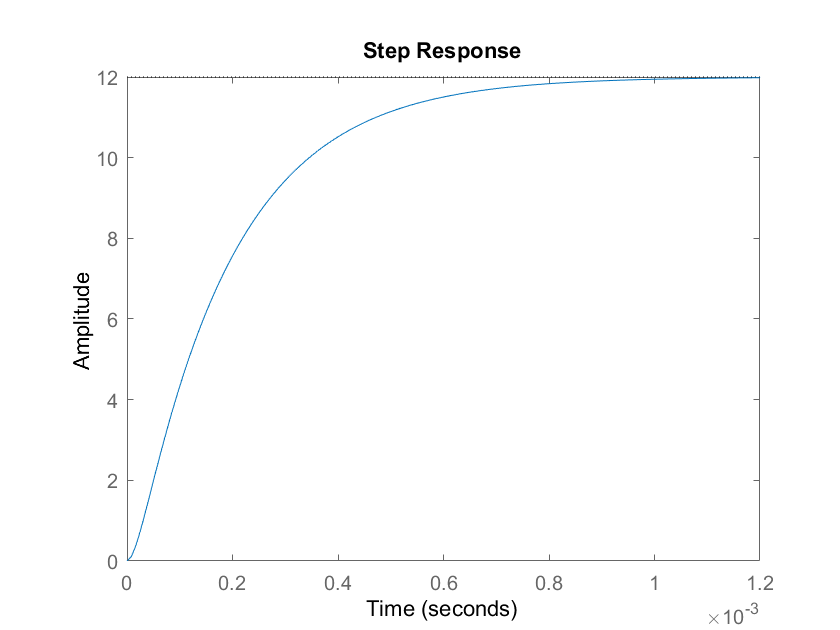

Am = [0 -1/L;1/C -1/(C*RL)];
Bm = [Vin/L 0]';
Cm = [0 1];
Dm = 0;

sys = ss(Am,Bm,Cm,Dm);

%Resposta em malha aberta ao degrau de D=0.5 
step(0.5*sys)

Em malha fechada, sem compensador o sistema tem a seguinte representação:

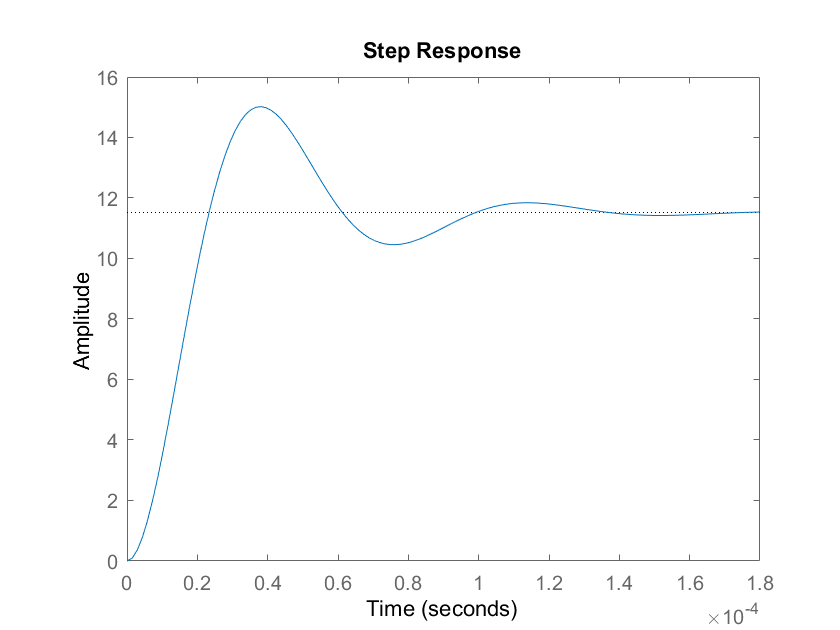

Amf = Am-Bm*Cm;
Bmf = Bm;
Cmf = Cm;
Dmf = Dm;

sysMF = ss(Amf,Bmf,Cmf,Dmf);

%Resposta em malha aberta ao degrau de 12 V
step(12*sysMF)


%Polos de MF sem compensação
eig(Amf)

ans = 	1.0e+04 *

  -3.1416 + 8.2867i
  -3.1416 - 8.2867i


## **Projeto do Controlador:**

Deseja-se erro nulo para entrada do tipo degrau e tempo de acomodação de 5 ms sem sobressinal.

Para zerar o erro precisamo inserir um integrador, pois a planta é do tipo 0. Criando as matrizes aumentadas para considerar o integrador que serão usadas no projeto dos ganhos do controlador:

Aaum = [Am zeros(2,1);-Cm 0];
Baum = [Bm ; 0];
Caum = [Cm 0];
Daum = 0;

Desejamos uma resposta transitória similar a de um sistema de primeira ordem com tempo de acomodação de 5 ms. Logo,  o polo dominante real deve ser:

 ts = 5e-3;
 a = 4/ts;
 polo_desejado1 = -a

polo_desejado1 = -800

O outro polo do sistema em malha fechada deve estar bem afastado do polo dominante desejado. Assim, escolhemos o segundo polo de malha fechada 30 vezes mais afastado do polo dominante. Isto é,

 polo_desejado2 = 30 * polo_desejado1

polo_desejado2 = -24000

O terceiro polo que surge em malha fechada devido ao integrador é escolhido estando afastado 50 vezes do polo dominante desejado.

 polo_desejado3 = 50 * polo_desejado1

polo_desejado3 = -40000

 Assim, os polos de malha fechada desejados após a compensação são:

 polos_MFD = [polo_desejado1 polo_desejado2 polo_desejado3]

polos_MFD =         -800      -24000      -40000


Para escolher os demais polos de malha fechada desejados, atente que mudar significativamente a dinâmica do sistema exigirá mais energia e os ganhos tenderão a serem maiores. Isso poderá levar o sistema real a saturar seu atuador. Para essa planta a variável de atuação é a razão cíclica que varia de 0 a 1. Para esse caso, os demais polos foram escolhidos  em -24000 e -40000. **Faça outras escolhas de polos e verifique o efeito na simulação do Simulink que faremos na sequência. **

Os ganhos do controlador são dados por:

 Kaum = acker(Aaum, Baum, polos_MFD);

Logo, os ganhos K1, K2 e Ki são:

 K1 = Kaum(1)

K1 = 0.0236

 K2 = Kaum(2)

K2 = 0.0760

 Ki = -Kaum(3)

Ki = 101.8592

O sistema em malha fechada compensado tem polos dados por:

 polos_MFC = eig(Aaum-Baum*Kaum)

polos_MFC = 	1.0e+04 *

   -4.0000
   -2.4000
   -0.0800


O sistema em malha fechada compensado tem a seguinte representação e resposta ao degrau de 12 V:

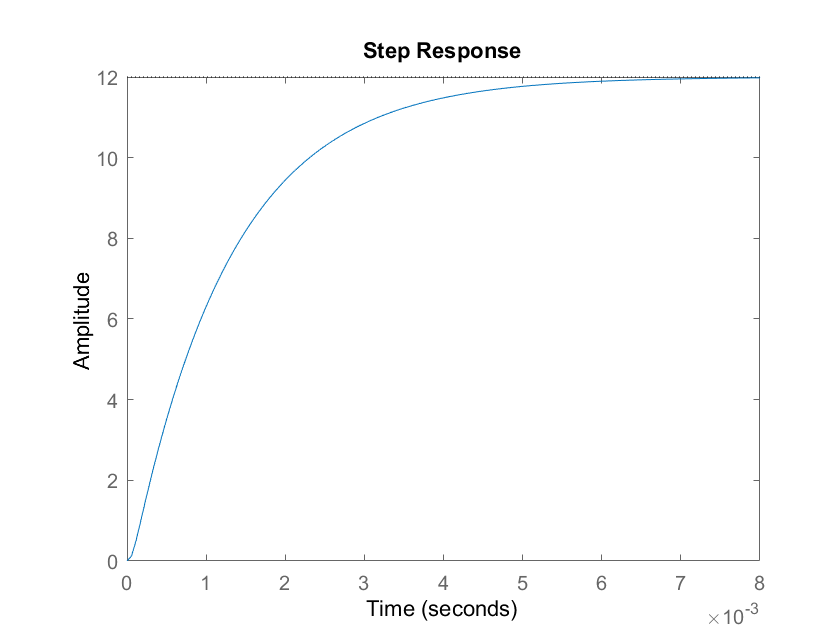

 Amfc = Aaum - Baum*Kaum;
 Bmfc = [zeros(2,1) ; 1];
 Cmfc = Caum;
 Dmfc = Daum;
 sysMFC = ss(Amfc,Bmfc,Cmfc,Dmfc);
 
 %Resposta a uma referência de 12V
 step(12*sysMFC)

Vamos verificar o comportamento do sistema em malha fechada com o controlador projetado para diferentes cargas.

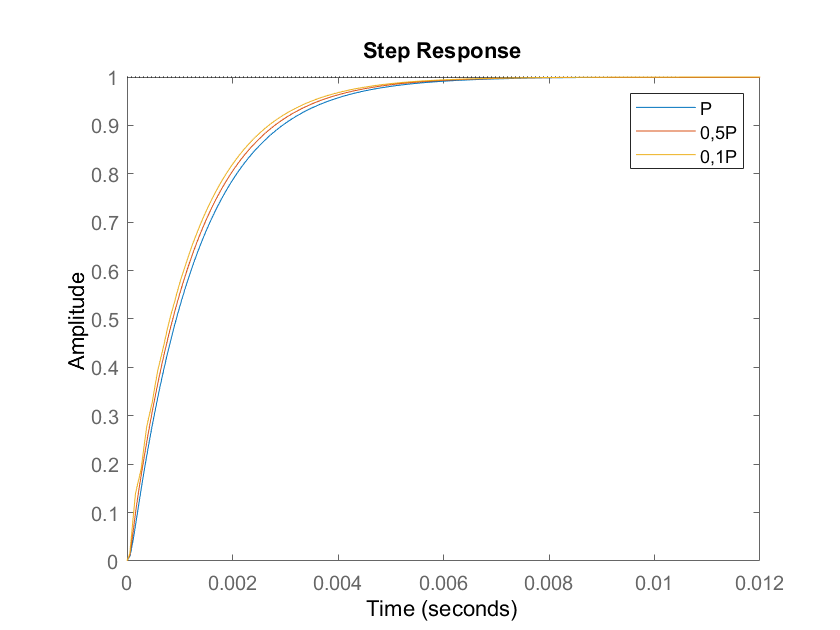

%Potência 50%
Am50 = [0 -1/L;1/C -1/(C*RL50)];
Aaum50 = [Am50 zeros(2,1);-Cm 0];
Amfc50 = Aaum50 - Baum*Kaum;
sysMFC50 = ss(Amfc50,Bmfc,Cmfc,Dmfc);


%Potência 10%
Am10 = [0 -1/L;1/C -1/(C*RL10)];
Aaum10 = [Am10 zeros(2,1);-Cm 0];
Amfc10 = Aaum10 - Baum*Kaum;
sysMFC10 = ss(Amfc10,Bmfc,Cmfc,Dmfc);

step(sysMFC,sysMFC50,sysMFC10);
legend('P','0,5P','0,1P')

Observe que, diferentemente, do exemplo em que foi projetado um PID para o problema, considerou-se a planta com a potência nominal para o projeto. Para o PID considerou-se a planta com 10% da potência. Fica como exercício considerar a planta com potência  de 10% da nominal para o projeto dos ganhos de realimentação de estados. Utilize o controlador obtido e verifique a resposta transitória para o sistema com potência nominal, 50% e 10% da potência nominal. Vai ficar evidente a escolha que foi feita no início do projeto para o modelo a ser considerado.

## **Projeto do Observador**

Inicialmente, vamos verificar a observabilidade do sistema:

N = obsv(Am,Cm)

N = 	1.0e+04 *

         0    0.0001
    9.0478   -6.2832


rank(N)

ans = 2

Os polos de malha-fechada do sistema controlado são:

polosMFC = eig(Amfc)

polosMFC = 	1.0e+04 *

   -4.0000
   -2.4000
   -0.0800


Como precisamos estimar apenas os estados da planta, vamos pegar os 2 autovalores mais rápidos do sistema controlado para definirmos os autovalores do observador:

u1 = 5*polosMFC(1);
u2 = 5*polosMFC(2);
autovalores_observador = [u1 u2]

autovalores_observador = 	1.0e+05 *

   -2.0000   -1.2000


O ganho do observador é calculado como:

Ke = acker(Am',Cm',autovalores_observador)'

Ke = 	1.0e+05 *

    2.6179
    2.5717
